# **변경사항**

**2022.01.25**

- `readVerticalWithoutTime` 추가

# **channerReader의 파일 유형별 read 함수 정리**

- `readBrainSingleChannel`

- `readRetinaWithoutTime`

- `readRetinaWithTime`

- `readMultiChannelFile`

- `readVerticalWithoutTime`

reader_LEGACY = channelReader(); % reader object 생성
reader_NEW = channelReader(); % reader object 생성

## `1. readBrainSingleChannel`

`MEA data.xlsx`와 같은 포맷

                - **3**번째 row부터 데이터 시작

                - row number가 써 있음

                - channel number가 써 있으나 chnnel이 하나밖에 없음

                - row마다 시작 시간이 기록되어 있음

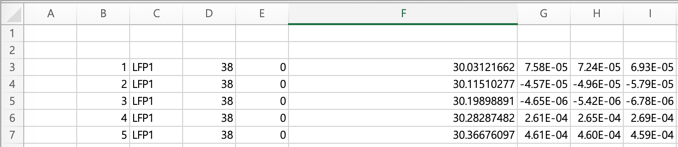

%                                           filename, organoid, channel, month 
test_1_LEGACY = reader_LEGACY.LEGACY_readBrainSingleChannel("./data/MEA data.xlsx", 1, 38, 1)

test_1_LEGACY =   channel - 속성 있음:

              organoidNum: 1.0000e+000
               channelNum: 38.0000e+000
                    month: 1.0000e+000
                       sf: 3.0518e+003
                  msPerTs: 327.6800e-003
              nTimestamps: 61.1830e+003
                startTime: 30.0312e+000
            endTimeApprox: 50.0793e+000
           durationApprox: 20.0481e+000
                        t: [1×61183 double]
                      raw: [1×61183 double]
                 filtered: []
        timestampsPrePeak: []
       timestampsPostPeak: []
          spikeTimestamps: []
    spikeTimestampsMatrix: []
           spikeWaveforms: []
                  nSpikes: []
                 PCScores: []
             explainedVar: []
                 clusters: []
                nClusters: []
        nSpikesPerCluster: []
     totalMeanSpikeStruct: []
         meanSpikesStruct: []
             ISIbeforePCA: []
    


test_1_LEGACY.raw

ans =     75.7580e-006    72.3870e-006    69.2580e-006    65.3220e-006    59.4930e-006    53.2050e-006    46.2750e-006    40.6200e-006    37.8240e-006    34.8720e-006    32.3270e-006    28.8460e-006    24.4330e-006    20.8080e-006    18.0450e-006    17.0840e-006    15.2150e-006    12.7060e-006     9.4803e-006     6.1701e-006     3.0746e-006   601.8617e-009  -860.7788e-009    -1.8296e-006    -1.9260e-006    -2.7241e-006    -5.6303e-006   -10.2499e-006   -13.4619e-006   -15.7039e-006   -17.5010e-006   -15.7411e-006    -6.9938e-006     4.9008e-006    14.7777e-006    23.7708e-006    29.0349e-006    32.3000e-006    32.1200e-006    31.4381e-006    25.1483e-006    15.1474e-006     1.8050e-006   -10.0096e-006   -19.0577e-006   -24.6139e-006   -26.3620e-006   -26.4160e-006   -26.8230e-006   -28.8549e-006


                                      
                                        % filename,     timeColumnIdx  startRowIdx   startColIdx   sampleRate   organoidNum   channelNum     month
test_1_NEW = reader_NEW.readSingleChannel("./data/MEA data.xlsx", 6,      3,             7,            0,           1,              38,            1)

test_1_NEW =   channel - 속성 있음:

              organoidNum: 1.0000e+000
               channelNum: 38.0000e+000
                    month: 1.0000e+000
                       sf: 3.0518e+003
                  msPerTs: 327.6800e-003
              nTimestamps: 61.1830e+003
                startTime: 30.0312e+000
            endTimeApprox: 50.0793e+000
           durationApprox: 20.0481e+000
                        t: [1×61183 double]
                      raw: [1×61183 double]
                 filtered: []
        timestampsPrePeak: []
       timestampsPostPeak: []
          spikeTimestamps: []
    spikeTimestampsMatrix: []
           spikeWaveforms: []
                  nSpikes: []
                 PCScores: []
             explainedVar: []
                 clusters: []
                nClusters: []
        nSpikesPerCluster: []
     totalMeanSpikeStruct: []
         meanSpikesStruct: []
             ISIbeforePCA: []
       

test_1_NEW.raw

ans =     75.7580e-006    72.3870e-006    69.2580e-006    65.3220e-006    59.4930e-006    53.2050e-006    46.2750e-006    40.6200e-006    37.8240e-006    34.8720e-006    32.3270e-006    28.8460e-006    24.4330e-006    20.8080e-006    18.0450e-006    17.0840e-006    15.2150e-006    12.7060e-006     9.4803e-006     6.1701e-006     3.0746e-006   601.8617e-009  -860.7788e-009    -1.8296e-006    -1.9260e-006    -2.7241e-006    -5.6303e-006   -10.2499e-006   -13.4619e-006   -15.7039e-006   -17.5010e-006   -15.7411e-006    -6.9938e-006     4.9008e-006    14.7777e-006    23.7708e-006    29.0349e-006    32.3000e-006    32.1200e-006    31.4381e-006    25.1483e-006    15.1474e-006     1.8050e-006   -10.0096e-006   -19.0577e-006   -24.6139e-006   -26.3620e-006   -26.4160e-006   -26.8230e-006   -28.8549e-006


## `2. readRetinaWithoutTime`

`Data 1.csv`와 같은 포맷

                - **8**번째 row부터 데이터 시작

                - channel number 써 있지 않음, chnnel이 하나밖에 없음

                - row마다 시작 시간이 기록되어 있지 않음

                        - 시작 시간을 알 수 없음 -> 0초에서 시작한 것으로 간주

                        - 각 row의 duration을 알 수 없음 -> sampling rate 정보 필요

%                                      filename, sampling rate(HZ), organoid, channel, month
test_2_LEGACY = reader_LEGACY.LEGACY_readRetinaWithoutTime("./data/Data 1.csv", 3152, 1,1,1);

파일의 마지막 열이 모두 공백 문자로 되어 있습니다. matlab은 공백 문자를 NaN으로 불러옵니다. 해당 열을 삭제했습니다.


test_2_LEGACY.raw

ans =    -51.0000e-006   -55.0000e-006   -57.0000e-006    -5.0000e-006   -31.0000e-006   -32.0000e-006   -30.0000e-006    17.0000e-006    -8.0000e-006     7.0000e-006   -28.0000e-006   -27.0000e-006   -19.0000e-006   -12.0000e-006    -8.0000e-006   -13.0000e-006     0.0000e+000   -19.0000e-006   -20.0000e-006   -33.0000e-006    -5.0000e-006   -11.0000e-006   -17.0000e-006     1.0000e-006     3.0000e-006    46.0000e-006    92.0000e-006    97.0000e-006    86.0000e-006    94.0000e-006    77.0000e-006    56.0000e-006    48.0000e-006    52.0000e-006    47.0000e-006    62.0000e-006    70.0000e-006    63.0000e-006    44.0000e-006    45.0000e-006    33.0000e-006    15.0000e-006   -10.0000e-006   -14.0000e-006   -25.0000e-006   -16.0000e-006   -19.0000e-006   -26.0000e-006   -14.0000e-006   -50.0000e-006



                                        % filename,     timeColumnIdx  startRowIdx   startColIdx   sampleRate     organoidNum   channelNum     month
test_2_NEW = reader_NEW.readSingleChannel("./data/Data 1.csv",      0,       8,             1,            3152,           1,              1,            1);

파일의 마지막 열이 모두 공백 문자로 되어 있습니다. matlab은 공백 문자를 NaN으로 불러옵니다. 해당 열을 삭제했습니다.


test_2_NEW.raw

ans =    -51.0000e-006   -55.0000e-006   -57.0000e-006    -5.0000e-006   -31.0000e-006   -32.0000e-006   -30.0000e-006    17.0000e-006    -8.0000e-006     7.0000e-006   -28.0000e-006   -27.0000e-006   -19.0000e-006   -12.0000e-006    -8.0000e-006   -13.0000e-006     5.0822e-021   -19.0000e-006   -20.0000e-006   -33.0000e-006    -5.0000e-006   -11.0000e-006   -17.0000e-006     1.0000e-006     3.0000e-006    46.0000e-006    92.0000e-006    97.0000e-006    86.0000e-006    94.0000e-006    77.0000e-006    56.0000e-006    48.0000e-006    52.0000e-006    47.0000e-006    62.0000e-006    70.0000e-006    63.0000e-006    44.0000e-006    45.0000e-006    33.0000e-006    15.0000e-006   -10.0000e-006   -14.0000e-006   -25.0000e-006   -16.0000e-006   -19.0000e-006   -26.0000e-006   -14.0000e-006   -50.0000e-006


            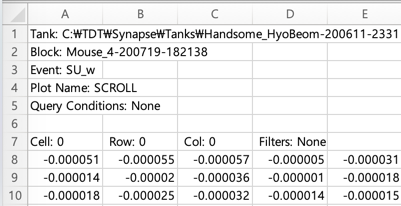

              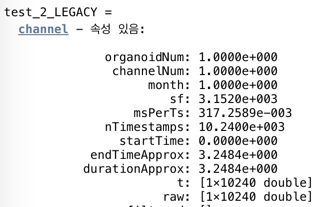       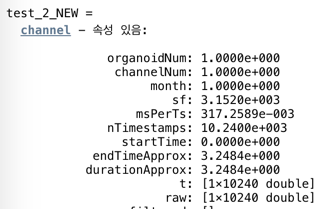

## `3. readRetinaWithTime`

`Data 2.csv`와 같은 포맷

                - **8**번째 row부터 데이터 시작

                - channel number 써 있지 않음, chnnel이 하나밖에 없음

                - row마다 시작 시간이 기록되어 있음

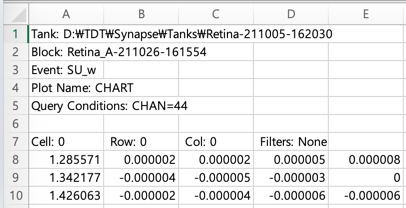

%                                      filename, organoid, channel, month
test_3_LEGACY = reader.LEGACY_readRetinaWithTime("./data/Data 2.csv", 1,1,1);

파일의 마지막 열이 모두 공백 문자로 되어 있습니다. matlab은 공백 문자를 NaN으로 불러옵니다. 해당 열을 삭제했습니다.
1행의 관측치 수가 1382로, 2048개인 다른 행보다 관측치 수가 적습니다.


test_3_LEGACY.raw

ans =      2.0000e-006     2.0000e-006     5.0001e-006     8.0001e-006     7.9999e-006     4.9998e-006     2.9999e-006   999.8442e-009   -13.8272e-012   -81.0601e-012    -1.0000e-006   118.1233e-012   -52.1717e-012    86.4814e-012     1.0002e-006     2.0001e-006     2.0000e-006     2.0000e-006     2.0000e-006     2.0002e-006     3.0000e-006     1.9996e-006   999.9525e-009   999.7612e-009    -1.0008e-006    -3.0003e-006    -2.9999e-006    -3.0000e-006    -3.0002e-006    -4.0003e-006    -3.9996e-006    -1.9991e-006   631.0659e-012     1.0002e-006   999.8066e-009  -751.7980e-012    -2.0008e-006    -3.0000e-006    -3.0004e-006    -3.9998e-006    -1.9987e-006   862.1409e-012   999.9382e-009  -652.8179e-012    -1.0006e-006    -2.0002e-006    -2.0003e-006    -3.0005e-006    -2.9996e-006    -1.9992e-006



                                        % filename,     timeColumnIdx  startRowIdx   startColIdx   sampleRate     organoidNum   channelNum     month
test_3_NEW = reader.readSingleChannel("./data/Data 2.csv",      1,       8,             2,            nan,           1,              1,            1);

파일의 마지막 열이 모두 공백 문자로 되어 있습니다. matlab은 공백 문자를 NaN으로 불러옵니다. 해당 열을 삭제했습니다.
1행의 관측치 수가 1382로, 2048개인 다른 행보다 관측치 수가 적습니다.


test_3_LEGACY.raw

ans =      2.0000e-006     2.0000e-006     5.0001e-006     8.0001e-006     7.9999e-006     4.9998e-006     2.9999e-006   999.8442e-009   -13.8272e-012   -81.0601e-012    -1.0000e-006   118.1233e-012   -52.1717e-012    86.4814e-012     1.0002e-006     2.0001e-006     2.0000e-006     2.0000e-006     2.0000e-006     2.0002e-006     3.0000e-006     1.9996e-006   999.9525e-009   999.7612e-009    -1.0008e-006    -3.0003e-006    -2.9999e-006    -3.0000e-006    -3.0002e-006    -4.0003e-006    -3.9996e-006    -1.9991e-006   631.0659e-012     1.0002e-006   999.8066e-009  -751.7980e-012    -2.0008e-006    -3.0000e-006    -3.0004e-006    -3.9998e-006    -1.9987e-006   862.1409e-012   999.9382e-009  -652.8179e-012    -1.0006e-006    -2.0002e-006    -2.0003e-006    -3.0005e-006    -2.9996e-006    -1.9992e-006


## `4.readVerticalWithoutTime`

`추가 데이터.xlsx `와 같은 포맷

                - 1번째 row부터 데이터 시작

                - channel number 써 있지 않음, chnnel이 하나밖에 없음

                - row마다 시작 시간이 기록되어 있지 않음

                        - 시작 시간을 알 수 없음 -> 0초에서 시작한 것으로 간주

                        - 각 row의 duration을 알 수 없음 -> sampling rate 정보 필요

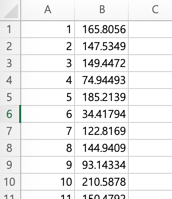

%                                      filename, sampling rate(HZ), organoid, channel, month
test_4_LEGACY = reader.LEGACY_readVerticalWithoutTime("./data/추가 data.xlsx", 3152, 1,1,1);
test_4_LEGACY.raw

ans =    165.8056e+000
   147.5349e+000
   149.4471e+000
    74.9449e+000
   185.2139e+000
    34.4179e+000
   122.8169e+000
   144.9409e+000
    93.1433e+000
   210.5878e+000


                                        % filename,     timeColumnIdx  startRowIdx   startColIdx   sampleRate     organoidNum   channelNum     month
test_4_NEW = reader.readSingleChannel("./data/추가 data.xlsx",      0,       1,             2,            3152,           1,              1,            1);
test_4_NEW.raw     

ans =    165.8056e+000   147.5349e+000   149.4471e+000    74.9449e+000   185.2139e+000    34.4179e+000   122.8169e+000   144.9409e+000    93.1433e+000   210.5878e+000   150.4792e+000   388.9525e+000   213.2909e+000   206.0806e+000    30.4465e+000   158.9292e+000   115.8411e+000    88.7666e+000   102.4869e+000   191.1007e+000   376.1257e+000   584.6794e+000   870.2903e+000   740.9847e+000   638.1597e+000   353.6130e+000   252.2014e+000   500.5673e+000   316.7908e+000   386.1571e+000   292.7951e+000   249.3476e+000   198.3855e+000   109.7787e+000   324.9920e+000   184.0081e+000   146.9067e+000   175.1105e+000   115.8615e+000    78.2980e+000    93.4808e+000   118.5596e+000   108.6285e+000    86.8496e+000    83.1694e+000   114.2330e+000   157.2559e+000   135.6254e+000   104.5685e+000    74.5490e+000


## `5.readMultiChannelFile`

`1_singleunit wave.xlsx, 전체.xlsx `와 같은 포맷

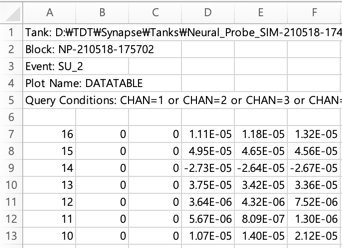     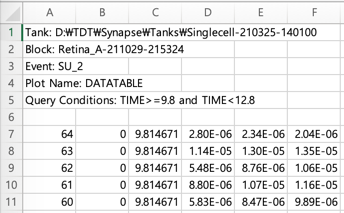

                - **7**번째 row부터 데이터 시작

                - channel number 기록되어 있음, chnnel이 여러 개 있음

                - row마다 시작 시간이 기록되어 있음

`readMultiChannelFile으로 파일 자체를 읽어온 다음, 아래의 두 가지 방법을 사용`

- `readSingleChannelFromFile: ``채널 번호를 특정하여 한 개의 채널의 데이터만 channel object로 만듦`

- `readManyChannelsFromFile: ``여러 채널 번호의 데이터를 channel object로 만듦. channel object의 리스트가 반환되며, {}로 인덱싱하면 개별 channel object가 나옴`

tic 
reader_LEGACY.LEGACY_readMultiChannelFile("./data/전체.xlsx"); %일단 파일을 불러옴
toc % 코드 실행 시간 측정. 오래 걸림.

경과 시간은 53.401199초입니다.


tic 
%                               filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader_NEW.readMultiChannelFile("./data/전체.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴

chReader =   channelReader - 속성 있음:

               massiveData: [2304×2051 double]
    massiveDataChannelRows: [2304×1 double]
            fileSampleRate: NaN
         fileTimeColumnIdx: 3.0000e+000
          fileBinTimeStart: [2304×1 double]


chReader =   channelReader - 속성 있음:

               massiveData: [2304×2048 double]
    massiveDataChannelRows: [2304×1 double]
            fileSampleRate: NaN
         fileTimeColumnIdx: 3.0000e+000
          fileBinTimeStart: [2304×1 double]


toc % 코드 실행 시간 측정. 오래 걸림.

경과 시간은 54.471736초입니다.



%                                      organoid, channel, month 
test5_LEGACY = reader_LEGACY.LEGACY_readSingleChannelFromFile(1, 8, 1) %8번 채널 데이터를 불러옴

test5_LEGACY =   channel - 속성 있음:

              organoidNum: 1.0000e+000
               channelNum: 8.0000e+000
                    month: 1.0000e+000
                       sf: 24.4141e+003
                  msPerTs: 40.9600e-003
              nTimestamps: 73.7270e+003
                startTime: 9.8147e+000
            endTimeApprox: 12.8345e+000
           durationApprox: 3.0198e+000
                        t: [1×73727 double]
                      raw: [1×73727 double]
                 filtered: []
        timestampsPrePeak: []
       timestampsPostPeak: []
          spikeTimestamps: []
    spikeTimestampsMatrix: []
           spikeWaveforms: []
                  nSpikes: []
                 PCScores: []
             explainedVar: []
                 clusters: []
                nClusters: []
        nSpikesPerCluster: []
     totalMeanSpikeStruct: []
         meanSpikesStruct: []
             ISIbeforePCA: []
        

test5_NEW = reader_NEW.readSingleChannelFromFile(1, 8, 1)

test5_NEW =   channel - 속성 있음:

              organoidNum: 1.0000e+000
               channelNum: 8.0000e+000
                    month: 1.0000e+000
                       sf: 24.4141e+003
                  msPerTs: 40.9600e-003
              nTimestamps: 73.7270e+003
                startTime: 9.8147e+000
            endTimeApprox: 12.8345e+000
           durationApprox: 3.0198e+000
                        t: [1×73727 double]
                      raw: [1×73727 double]
                 filtered: []
        timestampsPrePeak: []
       timestampsPostPeak: []
          spikeTimestamps: []
    spikeTimestampsMatrix: []
           spikeWaveforms: []
                  nSpikes: []
                 PCScores: []
             explainedVar: []
                 clusters: []
                nClusters: []
        nSpikesPerCluster: []
     totalMeanSpikeStruct: []
         meanSpikesStruct: []
             ISIbeforePCA: []
           

pixels_test6_LEGACY = reader_LEGACY.LEGACY_readManyChannelsFromFile(1, 1:64, 1);
%                                   organoid, array of channel numbers, month 

pixel1_test6_LEGACY = pixels_test6_LEGACY{1} % 64개 채널 중 첫 번째 채널

pixel1_test6_LEGACY =   channel - 속성 있음:

              organoidNum: 1.0000e+000
               channelNum: 1.0000e+000
                    month: 1.0000e+000
                       sf: 24.4141e+003
                  msPerTs: 40.9600e-003
              nTimestamps: 73.7270e+003
                startTime: 9.8147e+000
            endTimeApprox: 12.8345e+000
           durationApprox: 3.0198e+000
                        t: [1×73727 double]
                      raw: [1×73727 double]
                 filtered: []
        timestampsPrePeak: []
       timestampsPostPeak: []
          spikeTimestamps: []
    spikeTimestampsMatrix: []
           spikeWaveforms: []
                  nSpikes: []
                 PCScores: []
             explainedVar: []
                 clusters: []
                nClusters: []
        nSpikesPerCluster: []
     totalMeanSpikeStruct: []
         meanSpikesStruct: []
             ISIbeforePCA: []
 

pixel1_test6_LEGACY.raw

pixels_test6_NEW = reader_LEGACY.readManyChannelsFromFile(1, 1:64, 1);

ans =      4.0502e-006     7.3514e-006     9.3209e-006    10.9000e-006     8.1247e-006   -21.5990e-009    -4.2510e-006    -1.7682e-006     1.9032e-006     4.4037e-006     6.0214e-006     7.3219e-006     2.6543e-006    -9.3170e-006   -15.7300e-006   -12.7351e-006    -7.9731e-006    -4.7149e-006    -2.5727e-006  -774.6253e-009     3.6836e-006    11.3629e-006    15.9920e-006    15.7310e-006    14.3130e-006    13.3480e-006    12.6730e-006    11.9361e-006     4.8065e-006   -10.0607e-006   -18.7279e-006   -17.0481e-006   -13.2831e-006   -10.9750e-006    -9.7156e-006    -8.6810e-006   -11.7408e-006   -19.8838e-006   -24.1140e-006   -21.7321e-006   -18.1031e-006   -15.5231e-006   -13.7221e-006   -12.1600e-006   -15.0078e-006   -23.2758e-006   -27.4090e-006   -24.5501e-006   -20.4021e-006   -17.4041e-006


%                                   organoid, array of channel numbers, month 

pixel1_test6_NEW = pixels_test6_NEW{1} % 64개 채널 중 첫 번째 채널

pixel1_test6_NEW =   channel - 속성 있음:

              organoidNum: 1.0000e+000
               channelNum: 1.0000e+000
                    month: 1.0000e+000
                       sf: 24.4141e+003
                  msPerTs: 40.9600e-003
              nTimestamps: 73.7270e+003
                startTime: 9.8147e+000
            endTimeApprox: 12.8345e+000
           durationApprox: 3.0198e+000
                        t: [1×73727 double]
                      raw: [1×73727 double]
                 filtered: []
        timestampsPrePeak: []
       timestampsPostPeak: []
          spikeTimestamps: []
    spikeTimestampsMatrix: []
           spikeWaveforms: []
                  nSpikes: []
                 PCScores: []
             explainedVar: []
                 clusters: []
                nClusters: []
        nSpikesPerCluster: []
     totalMeanSpikeStruct: []
         meanSpikesStruct: []
             ISIbeforePCA: []
    

pixel1_test6_NEW.raw

ans =      4.0502e-006     7.3514e-006     9.3209e-006    10.9000e-006     8.1247e-006   -21.5990e-009    -4.2510e-006    -1.7682e-006     1.9032e-006     4.4037e-006     6.0214e-006     7.3219e-006     2.6543e-006    -9.3170e-006   -15.7300e-006   -12.7351e-006    -7.9731e-006    -4.7149e-006    -2.5727e-006  -774.6253e-009     3.6836e-006    11.3629e-006    15.9920e-006    15.7310e-006    14.3130e-006    13.3480e-006    12.6730e-006    11.9361e-006     4.8065e-006   -10.0607e-006   -18.7279e-006   -17.0481e-006   -13.2831e-006   -10.9750e-006    -9.7156e-006    -8.6810e-006   -11.7408e-006   -19.8838e-006   -24.1140e-006   -21.7321e-006   -18.1031e-006   -15.5231e-006   -13.7221e-006   -12.1600e-006   -15.0078e-006   -23.2758e-006   -27.4090e-006   -24.5501e-006   -20.4021e-006   -17.4041e-006
